# Evaluate Performance of MTHVDC Systems with GFM Control for Offshore Wind Integration

This project evaluates the performance of multi-terminal high voltage direct current (MTHVDC)  for transporting electrical power from offshore wind farms to the grid. The project investigates various controls for the HVDC stations including grid-forming (GFM) control.   

Use the tools provided in this project to design a MTHVDC systems, connect them to offshore renewable sources and evaluate their performance under dynamic scenarios like faults, large variations in renewable power, and load switching. 

## **MTHVDC Systems**

MTHVDC system have more than two converter stations interconnected by DC transmission lines, enabling power transfer between multiple locations. They offer several advantages over traditional ac (Alternating Current) systems and even conventional point-to-point HVDC systems.

    Flexibility - Ability to connect multiple power sources and loads.

    Reliability -  Enhanced redundancy and fault tolerance.

    Efficiency - Optimized power flow and reduced transmission losses.

The key components of MTDC systems are voltage source converters (VSCs), control systems, and protection systems. VSCs enable flexible and efficient control of power flow. They are capable of fast dynamic response and voltage regulation. Control systems ensure coordinated operation of multiple terminals. Protection systems protect against faults for safe and reliable operation.

### Bipolar HVDC Transmission

The bipolar HVDC system has two high-voltage conductors, one positive (+) and one negative (−), relative to a common ground (earth). This setup is different from the simpler monopolar HVDC system, which uses a single conductor.

 - The positive pole carries positive high voltage DC.

 - The negative pole carries negative high voltage DC.

 - The ground return provides continuity of service if one of the poles suffers an outage.

This figure shows a HVDC interconnection with bipolar HVDC stations.

                                  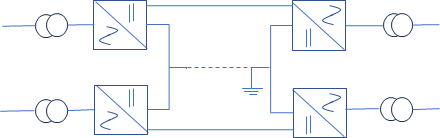

  The converter stations convert AC to DC at the sending end (rectifier) and DC to AC at the receiving end (inverter). The two DC transmission lines (one positive and one negative) transmit DC power. The Ground Electrodes provide a return path for current in the event of a fault.

### Offshore Wind Farm Integration using VSC HVDC

This project uses a VSC-based  HVDC system to connect distant offshore wind farms to the grid.

This figure shows the model that connects a wind farm unit to the AC grid through VSC-HVDC. The VSC HVDC network consists of HVDC stations which connect through a DC submarine cable. 

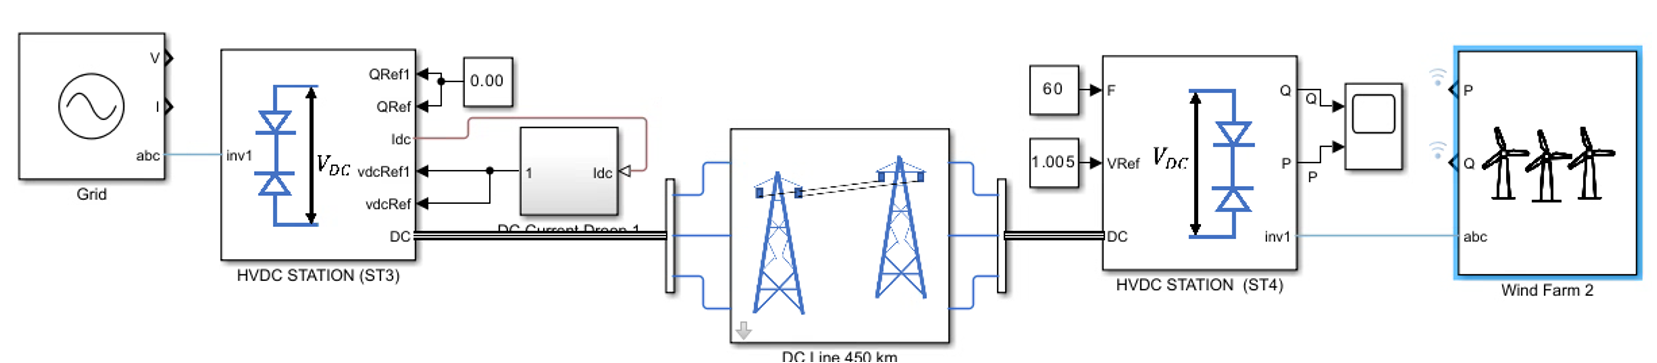

You can test the functioning of the HVDC station controllers using the VSCHVDCunit model. This figure shows the ability of the dc voltage controller to track the reference voltage.

                                                      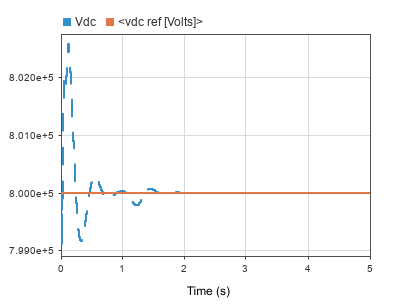

## **Wind Turbine Test Harness**

In this project, the wind turbines connect to the offshore wind farm using fully-rated back-to-back converters, where each wind turbine can generate a rated power of 18 MW at a wind speed of 11 m/s. This figure shows the power vs turbine rpm, characteristics plot for the wind turbine. The power output from each generator is 17.6 MW accounting for a 2% loss in the conversion system.

.

                                                                  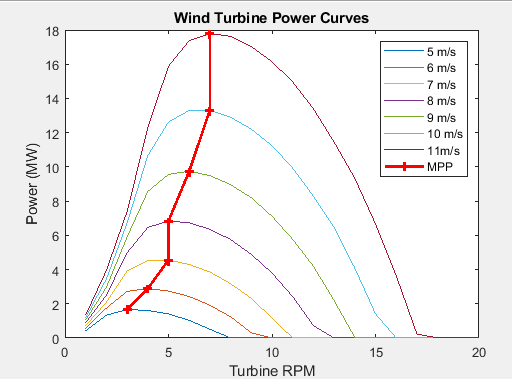

You can use the model, `testWT.slx`, to obtain this characteristic plot for the wind turbine. The test model is shown in this figure.

           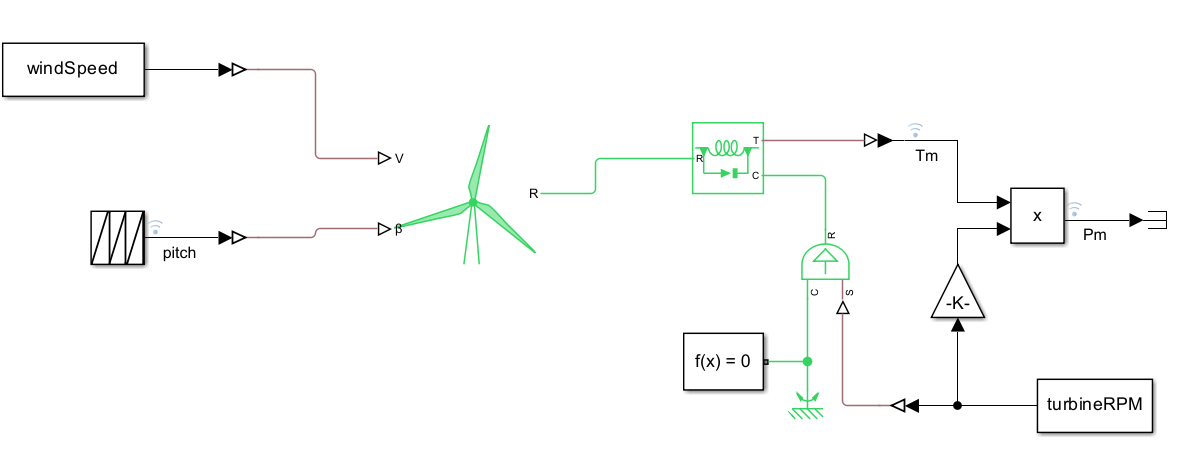

## HVDC Station Controllers 

  You can configure the station controllers in most VSCHVDC interconnections,. In general, the offshore stations is responsible for establishing the AC voltage for the wind farm, and the grid side onshore station is responsible for controlling the dc voltage and delivering the power to the AC grid.

   This figure shows the general control architecture of  VSC HVDC stations.

                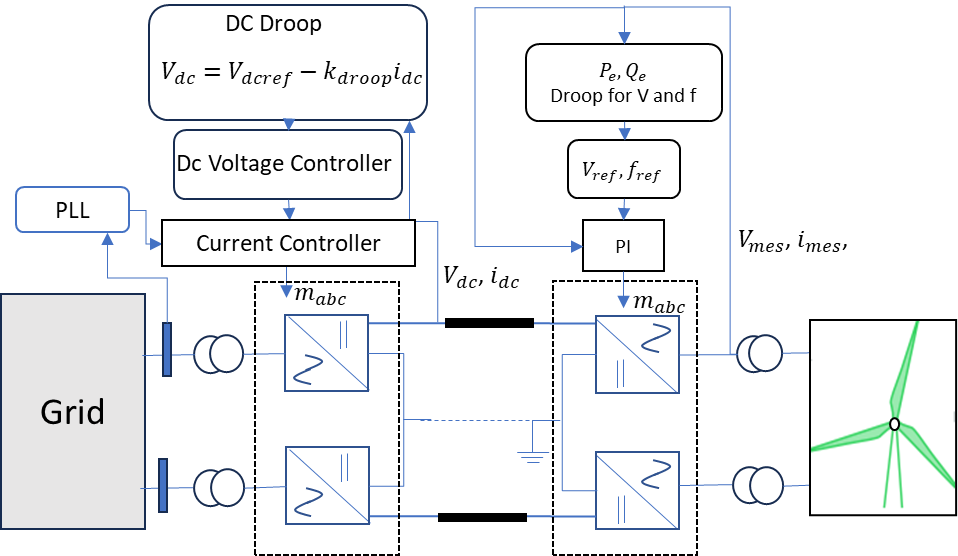

       The VSC HVDC system uses a hierarchical control structure:

          Inner control -  This loop controls the converter's AC and DC currents, providing fast response and stabilizing power exchange.

         Outer control  -  This loop controls the AC/ DC voltage and the power output of the converter stations to a desired reference using proportional integral controllers, this controller generates the  current reference for the inner controllers.

        DC Voltage Control - This controller maintains a stable DC-link voltage to balance the power between the AC and DC sides.

        Power Control - Control the amount of active power transferred to or from the DC system, allowing precise regulation of energy exchange with the AC network.

All the controllers are designed in the synchronous, dq, reference frame, which allows for independent control of the state variables: d- and q- axis voltages and currents.

### HVDC Station and Controllers as subsystem References   

  This project also provides you with the HVDC station and its controllers as reference subsystems. You can use to build your HVDC model, you can provide the controller parameters, filter parameters, and the base ratings of the station through the mask of the controllers.

  This figure shows the bipolar HVDC station subsystem with its mask.

     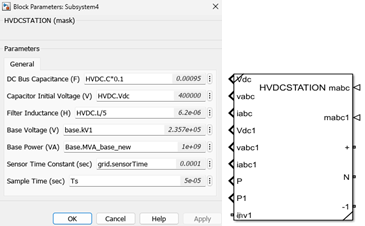

  This figures shows the different types of HVDC station controllers that are available with the project.

   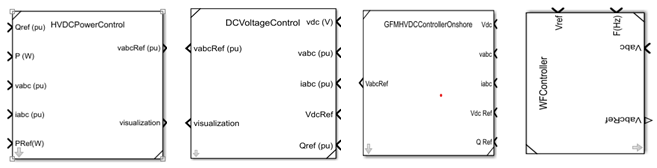

      HVDC Power Controller      DC Bus Voltage Controller     GFM Controller (Onshore)   GFM Controller (Offshore)

## Multi-Terminal VSC HVDC for Offshore Wind Integration

This project evaluates the performance of various control functions for offshore wind integration using MTHVDC network. The multi-terminal setup is particularly useful for interconnecting multiple renewable energy sources and share power over a single DC network to create redundancy for a reliable and resilient grid.

In this project you can find this model, `MTHVDCGW.slx, `which integrate two offshore wind farm sites to the AC grid through multiple HVDC lines.  

This figure shows the MTHVDC system for offshore wind integration.

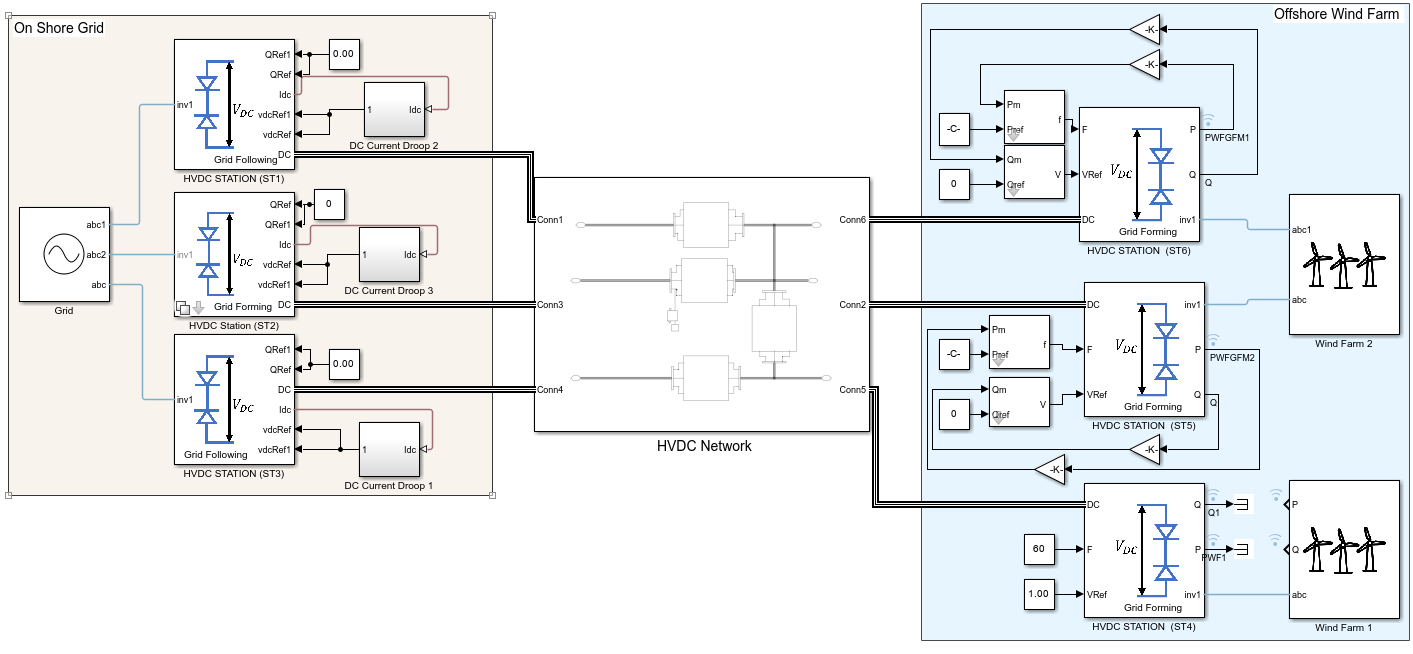

The DC network operates at 800 kV and connects the three offshore stations to the onshore stations. There is also a DC line connects the two offshore stations to exchange power between the sites. The wind farms are connected to the offshore station using AC submarine cables.

This figure shows the HVDC network. 

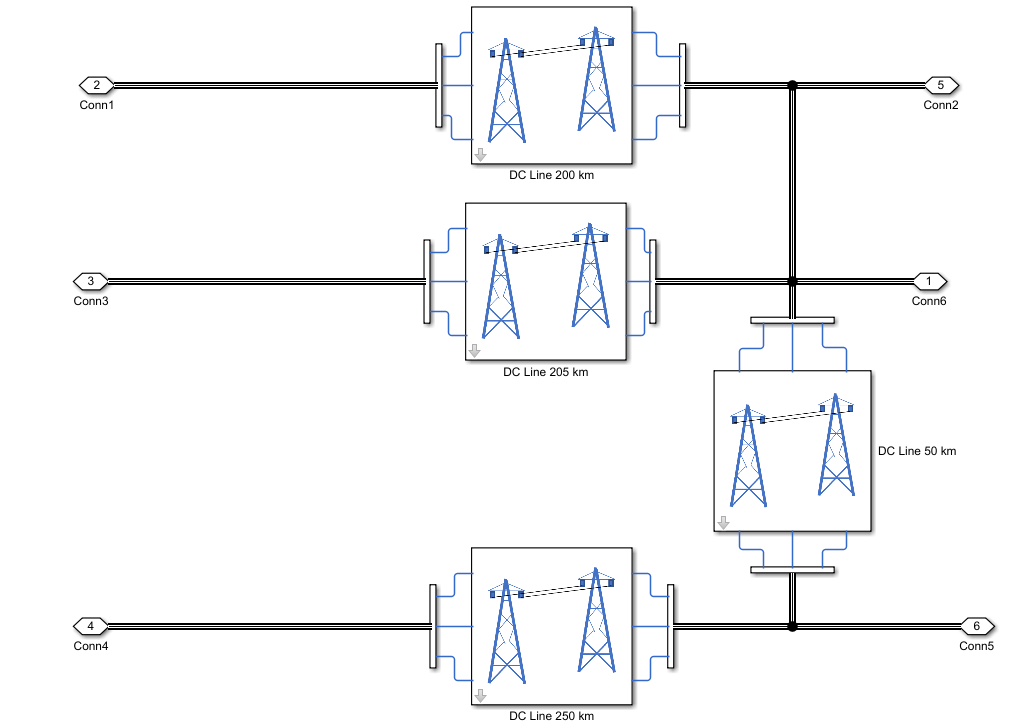

### **Converter Station Controllers**

This project uses six converter stations and their controllers to exchange power from the wind farm to the grid. 

The offshore converter stations have been configured to control the frequency and voltage magnitude of the wind farm. The first offshore wind farm site has one converter station, station 4,  which is operating in a  grid forming mode like an voltage source with constant frequency and voltage which can absorb all the active power from the wind farm and push it the DC network. The second offshore wind farm has two converter stations, station 5 and station 6, which are operating in grid forming mode but with droop controllers and they share the total wind power output based on their ratings. 

The three onshore converter stations connect to the onshore AC grid at three locations. Two HVDC stations, station 1 and station 2, are operating in grid following mode which export the power from the DC link to the onshore AC grid, while controlling the HVDC bus voltage. You use the voltage vs current droop to generate the DC-link voltage references for these stations. This allows the converter stations to share the DC-side power based on their ratings.

The onshore station 3 operates in GFM mode. The station controls the voltage and frequency at the point of interconnection using a virtual inertial-based controller. This allows the system to inject more renewable power into the grid without exceeding the voltage and frequency variation limits. The controller uses the energy stored in the DC link of the converter as the primary source of inertial energy for regulating the AC voltage and frequency at the inverter terminals.

The  power imbalance equation of the DC side capacitor can be  expressed as:

                                    $P_{inv}-P_{grid}=\frac{dE_{c}}{dt}\\ E_{c}=\frac{1}{2}CV_{c}^2\\
P_{inv}-P_{grid}=CV_{c}\frac{dV_{c}}{dt}$             (1)

The above equations are in the similar form as that of a synchronous generator swing equation, which is:

                                             $P_{SM}-P_{grid}=J\omega\frac{d\omega}{dt}$                              (2)

Comparing the two set of equation gives, $J\omega\frac{d\omega}{dt}=CV_c\frac{dV_c}{dt}$

Thus, from the above equations you can see that the the capacitor can add inertial power to the system.

This figure shows the frequency and voltage magnitude control  block diagrams of the GFM controller.

                        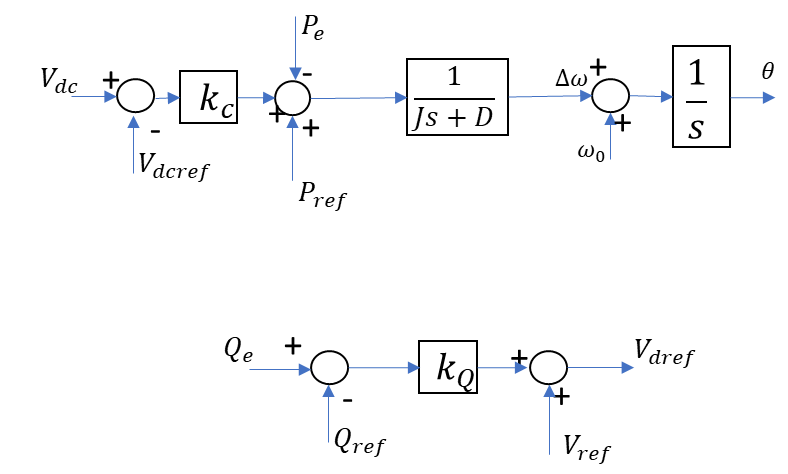

## **Grid Code Compliance**

  The VSC HVDC system should be able to support AC grid stability and manage disturbances. These capabilities are one of the most basic requirements included in most grid codes. 

  The station controller includes the following functions to comply with grid code requirements:

### ** Fault Ride-Through (FRT) requirements**

 To comply with fault ride-through (FRT) requirements you must maintain operation during AC faults, ensuring that the VSC HVDC station remains connected and contributes to grid recovery.

   Current limiting — To prevent overloading the converter, you can limit the AC fault current, often by prioritizing active or reactive components depending on the fault type.

   Reducing offshore wind power — To prevent the DC voltage increasing to unacceptable levels, you can reduce the power delivered by the offshore grid to the DC network, during faults.Dynamic    

   Reactive power support —  To support grid voltage recovery after fault clearance, the converter can temporarily increasing the reactive power output.

### ** Voltage and reactive power control requirements**

   The onshore HVDC stations  are required to control reactive power or regulate AC voltage at their connection points. Grid codes  specify dynamic reactive power support and voltage limits at the point of interconnection.

### ** Frequency and active power control requirements**

   The onshore HVDC station contributes to frequency regulation by dynamically adjusting the voltage and frequency at the onshore . It may also require to emulate inertia to provide immediate support  during  rapid frequency changes, especially in low-inertia grids.

   In this project we have designed the station controllers such that the offshore wind power is exported to the grid while complying with the above grid code requirements.

## Configure Model, Run Simulation, and Plot Results

### Simulation Settings

**Selecting Scenario**

In this example, you test the performance of the MTHVDC  system for offshore wind farm integration by simulating these scenarios:

**   Temporary Fault **— Create a three-phase-to-ground (LLLG) fault and clear it after 200 milliseconds.

**    Oscillation Damping after a Large Load Change  **— Simulate a sudden load change by increasing the load connected to the HV side of the onshore transformer. 

**    Wind Speed Variation **— Simulate a sudden reduction of wind power by curtailing the wind speed by 15%

You can run this simulation at a time step of 50 micro-seconds with Backward Euler as the local solver method. The local solver absolute and relative tolerances are set to $10^{-3}$.

### Choose the type of controller for the onshore station 3

This model gives you the option to switch between a GFM and and a grid following (GFL) controller for the onshore HVDC station 3. Using this controllers, you the observe the stabilizing affect of using GFM control during high wind penetration.

This figure shows the mask of the HVDC station 3 which you can use to switch the controllers.

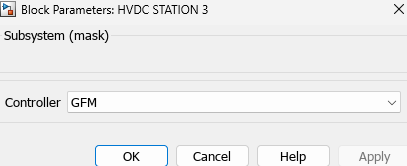

## Results and Discussion

### **Case 1: Temporary fault on the onshore grid**

In this study, you reduce the grid strength to SCR<3 by increasing the grid impedance. You simulate an onshore fault scenario to test the performance of the system with different controllers.

You compare the results using a GFL controller and a GFM controller at station 3.

#### **Test with GFL controller at station 3**

%Simulation settings for creating onshore fault near station 3
mdl='HVDCMTGW.slx'; % Test model with IBR plant

open_system(mdl);% Loading the model
time.fault=1;% Configure variable parameters using simulation input

if false % Tick this block to run simulation else use the already generated data
set_param('HVDCMTGW/HVDC STATION 3','Choice','GFL'); % Set Station 3 Controller to GFM control
Data1=sim(mdl);% Simulate model
else
    load Data1
end

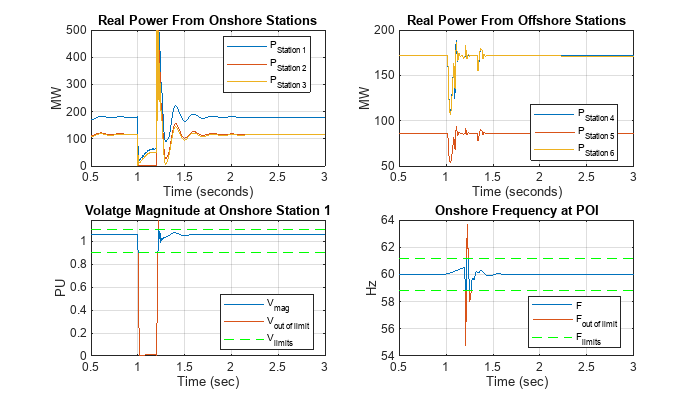

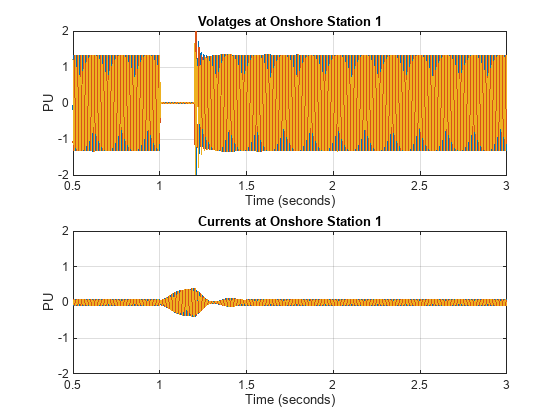

plotHVDC(Data1,Tsim);

As already discussed, the post-fault recovery standard requires the system to return to its pre-fault state within 0.5 sec once the fault is cleared. 

Observe the response of the HVDC stations during a three-phase to ground (LLLG) fault occurring on the transmission line connecting station 1 to the grid. The fault happens at 1.0 sec and clears after 200 ms. From the response of the HVDC stations  during the disturbance, it is clear that the MTHVDC system is unable able to return immediately to the pre-fault state after the fault is cleared, as the power from the HVDC stations oscillates for some time after the fault is cleared, which may result in non-compliance with the ride-through requirements in standards. 

#### **Test with GFM controller at station 3**

if false % Tick this block to run simulation else use the already generated data
set_param('HVDCMTGW/HVDC STATION 3','Choice','GFM'); % Set Station 3 Controller to GFM control
Data2=sim(mdl);% Simulate model
else
    load Data2
end

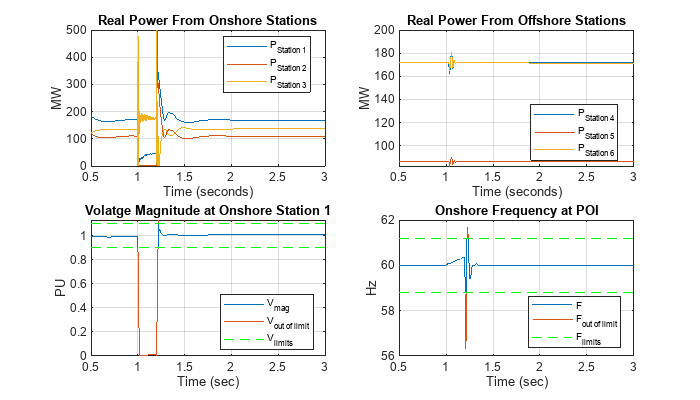

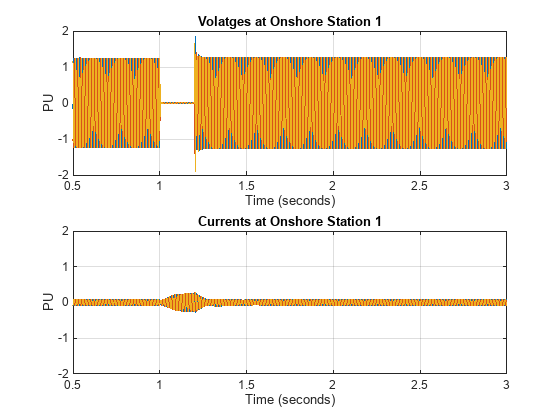

plotHVDC(Data2,Tsim);

Observe the response of the HVDC stations during a three-phase to ground (LLLG) fault occurring on the transmission line connecting station 1 to the grid. The fault happens at 1.0 sec and clears after 140 ms. From the response of the HVDC stations  during the disturbance, it is clear that the MTHVDC system is able to return to the pre-fault state after the fault is cleared,, without significant oscillations, which is in compliance with the ride-through requirements in standards. 

### **Case 2: Sudden Load drop on the onshore grid **

A load disturbance scenario is simulated by switching off a 200 MW load, this is done to test the oscillation damping capability of the GFM and GFL HVDC station controllers.

#### **Test with GFL controller at station 3**

time.fault=11;% Configure variable parameters using simulation input
time.load=1;% Configure variable parameters using simulation input

if false % Tick this block to run simulation else use the already generated data
set_param('HVDCMTGW/HVDC STATION 3','Choice','GFL'); % Set Station 3 Controller to GFM control
Data3=sim(mdl);% Simulate model
else
    load Data3
end

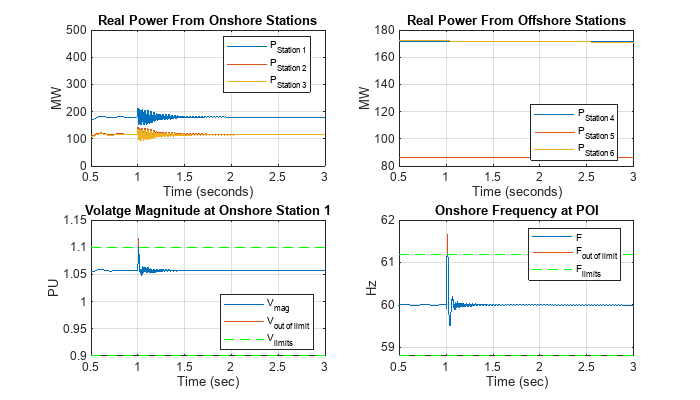

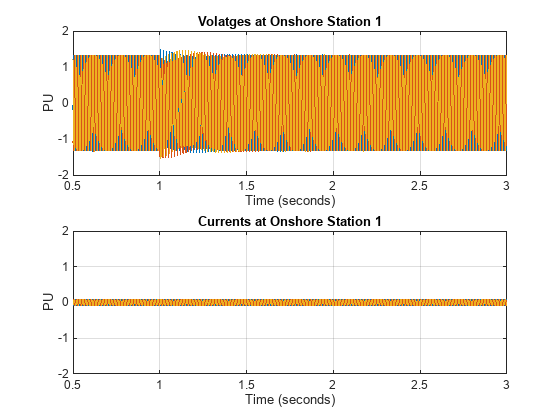

plotHVDC(Data3,Tsim);

From the above figures ,you can see that with only GFL controllers, their is a significant oscillation voltage at the POI and in the real power from the stations, post load change. 

#### **Test with GFM controller at station 3**

if false % Tick this block to run simulation else use the already generated data
set_param('HVDCMTGW/HVDC STATION 3','Choice','GFM'); % Set Station 3 Controller to GFM control
Data4=sim(mdl);% Simulate model
else
    load Data4
end

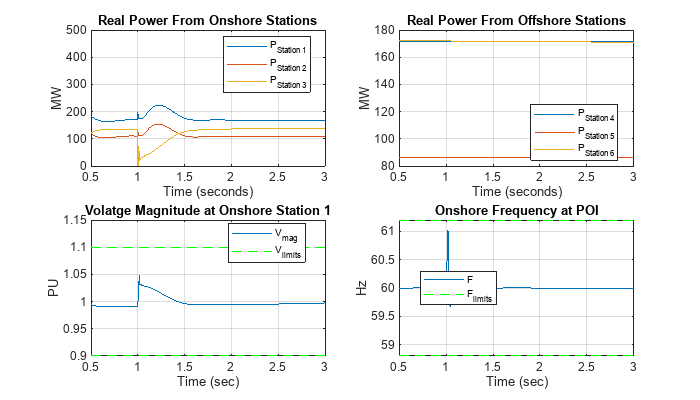

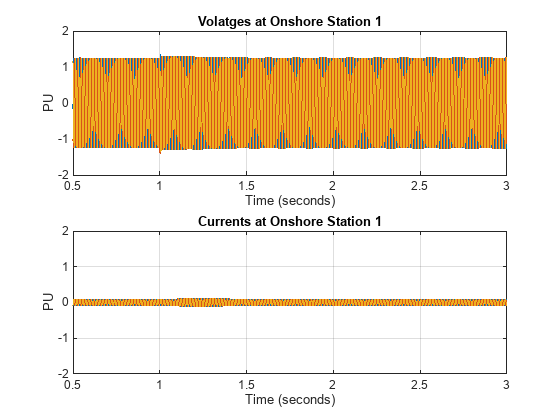

plotHVDC(Data4,Tsim);

From the above figures ,you can see that with a GFM controller, the oscillations are damped quickly and there are no oscillations in voltage or power at the POI , post load change. 

### **Case 3: Load drop followed by a three-phase fault on the onshore grid**

You simulate an onshore fault after a load change, the load in the system is tripped at 0.5 sec which effectively increases the share of wind power into the network. This system is subjected to an onshore fault at, 1.0 sec and cleared at 1.2 sec, to test the fault recovery performance under this condition.

#### **Test with GFL controller at station 3**

time.fault=2;% Configure variable parameters using simulation input
time.load=1;% Configure variable parameters using simulation input
Tsim=3;

if false % Tick this block to run simulation else use the already generated data
set_param('HVDCMTGW/HVDC STATION 3','Choice','GFL'); % Set Station 3 Controller to GFM control
Data5=sim(mdl);% Simulate model
else
    load Data5
end

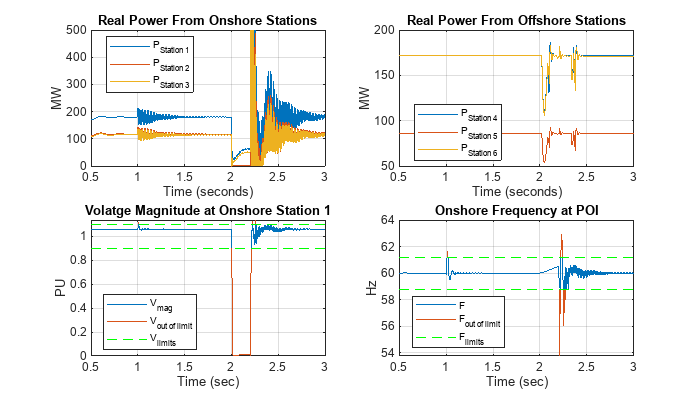

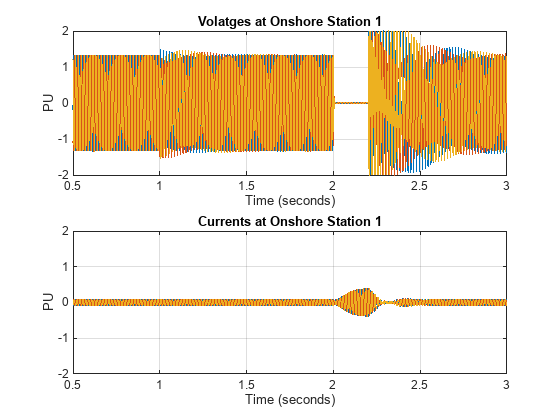

plotHVDC(Data5,Tsim);

From the above figures ,you can see that with only GFL controllers, their is a significant oscillation voltage at the POI and in the real power from the stations, post fault clearing. 

#### Test with GFM controller at station 3

When this system is subjected to an onshore fault at, 1.0 sec and cleared at 1.2 sec. You can see that with the GFM controller, their are no oscillations in voltage or  power from the stations, post fault clearing. The GFM controller improves the transient performance of the system, and helps the MTDC system to comply with grid codes.

if false % Tick this block to run simulation else use the already generated data
set_param('HVDCMTGW/HVDC STATION 3','Choice','GFM'); % Set Station 3 Controller to GFM control
Data6=sim(mdl);% Simulate model
else
    load Data6
end

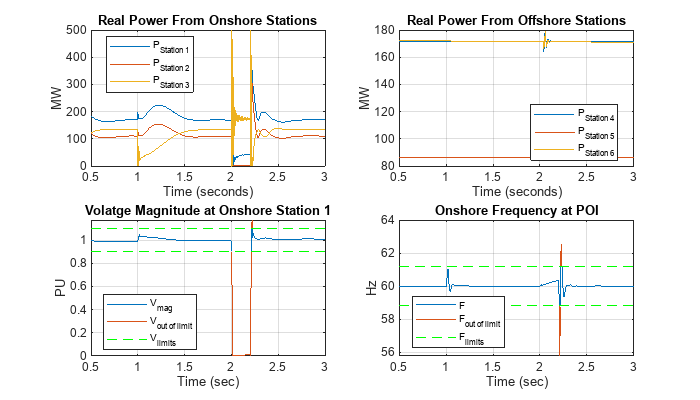

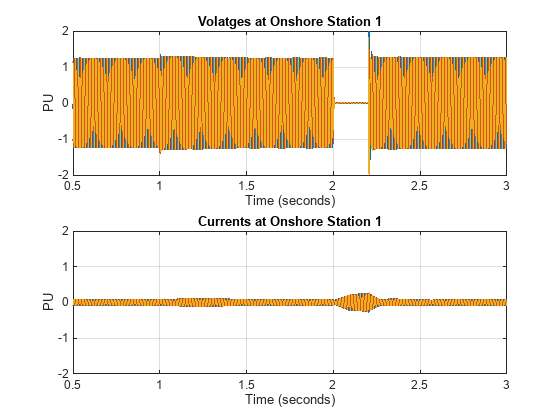

plotHVDC(Data6,Tsim);

## **Summary**

This project demonstrates the effectiveness of using GFM control for HVDC stations in maintaining a stable power system with high offshore wind penetration. Using the tools provided in this project you can design your own MTHVDC system and study the effect of various HVDC station control schemes. 

## References

1. Liang, J., Jing, T., Gomis-Bellmunt, O., Ekanayake, J. and Jenkins, N., 2011. Operation and control of multiterminal HVDC transmission for offshore wind farms. *IEEE Transactions on Power Delivery*, *26*(4), pp.2596-2604.

2. Korompili, A., Wu, Q. and Zhao, H., 2016. Review of VSC HVDC connection for offshore wind power integration. *Renewable and Sustainable Energy Reviews*, *59*, pp.1405-1414.